# **ECON 310: Dynamic Macroeconomics**

### **Spring 2025**

### **Fulbright University Vietnam**

%{

    run_vfi_sgm.mlx
    ---------------
    This code solves the stochastic growth model using value function iteration.

%}

## Model: Stochastic Growth Model.

The social planner's problem is


$$\underset{\{c_t\}_{t=1}^{\infty},\{k_{t+1}\}_{t=1}^{\infty}}{\text{max }} \mathbb{E}_0\sum_{t=1}^\infty \beta^{t} \frac{c_t^{1-\sigma}}{1-\sigma} \text{ ,}$$


 
$$\begin{array}{r l} \text{s.t. } y_t = c_t+i_t \end{array} \ ,$$


 
$$\begin{array}{r l} y_t = A_t k_t^{\alpha} \end{array} \ ,$$


 
$$\begin{array}{r l} k_{t+1} = (1-\delta)k_t + i_t \end{array} \ ,$$


 
$$\begin{array}{r l} \text{log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ ,$$



$$c_t > 0,  k_t > 0 \ ,$$


where $|\rho| < 1$, $\epsilon_{t+1}\sim\mathcal{N}(0,\sigma^2_{\epsilon})$, and the constraints hold for $t = 1, 2, ...,$. The rationale for the constraints that are similar to those in the deterministic growth model. The productivity term, $A_t$, is a stationary AR(1) in logs by assumption, but is based on empirical literature. This stochastic process is what the conditional expectations operator, $\mathbb{E}_0(\cdot)$, is applied to.

## Recursive Formulation.

The recursive formulation, combining the constraints into one, is


$$V_t(k_t,A_t) = \underset{c_t, k_{t+1}}{\text{max}}\frac{c_t^{1-\sigma}}{1-\sigma} + \beta \mathbb{E}_t\left[V_{t+1}(k_{t+1},A_{t+1})\right] \ ,$$


 
$$\begin{array}{r l} \text{s.t. } A_tk_t^{\alpha} =  c_t + k_{t+1} - (1-\delta)k_t \end{array} \ \text{for} \ t = 1, 2, ... \ ,$$


 
$$\begin{array}{r l} \text{log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ .$$



$$c_t > 0,  k_t > 0 \text{ .}$$


Because of the productivity shocks, the state space has now expanded to include this. Substituting the combined constraint into the utility function gives


$$V_t(k_t,A_t) = \underset{k_{t+1}}{\text{max}}\frac{\left(A_tk_t^{\alpha}+(1-\delta)k_t-k_{t+1}\right)^{1-\sigma}}{1-\sigma} + \beta \mathbb{E}_t\left[V_{t+1}(k_{t+1},A_{t+1})\right] \ ,$$


 
$$\begin{array}{r l} \text{s.t. log}(A_{t+1}) = \mu + \rho\text{log}(A_t) + \epsilon_{t+1} \end{array} \ ,$$



$$k_t > 0 \ ,$$


simplifying the problem as before.

## Set up directories and paths.

clc
clear
close all

id = getenv('USERNAME'); % Gets your username.

main = strcat('/Users/USER/Documents/GitHub/Dynamic-Macro_Inclass-code/'); % Project Folder.
cd (strcat(main)) % Set project folder as current working directory.

addpath(genpath(main)) % Add all subfolders in current working directory to path. Note: Make sure file names are unique.
figout = strcat(main,'output/figures/'); % Folder for figures.

fprintf('The directory is %s \n\n',main)

The directory is /Users/USER/Documents/GitHub/Dynamic-Macro_Inclass-code/ 



## Set the parameters and generate the state space.

Calls: model.m.

We cannot directly compute the steady state capital as before because of the productivity fluctuations, but we can still build the grid for $k_t$ around the deterministic steady state.

par = model.setup; % Set parameters.
par = model.gen_grids(par); % Generate the state space.

## Solve the model using Value Function Iteration.

Calls: solve.m, and model.m.

As in the deterministic case, we will solve the model using value function iteration using 


$$V(k_t) = \frac{1}{1-\beta} \frac{\left(A_tk_t^{\alpha}-(1-\delta)k_t\right)^{1-\sigma}}{1-\sigma} \ ,$$


as a guess.

t = cputime;
sol = solve.cs_model_fin(par); % Solve the model using Value Function Iteration.

------------Beginning Backward Induction.------------

------------End of Backward Induction.------------


fprintf('\nModel solved in %0.4f seconds.\n',cputime-t)


Model solved in 0.0938 seconds.


## Simulate the model and plot the model functions and time series.

Calls: simulate.m and my_graph.m.

The model functions behave in a similarly to those in the deterministic growth model. The difference now is that because there are different levels of productivity, there will be a separate function for each level. For example, the seven production functions correspond to different levels of $A_t$. The blue line is production at the lowest level of $A_t$ while the red line is production at the highest level. The general pattern is that the higher $A_t$ is, the more resources there are for consumption, saving, and investment.

Because of productivity fluctuations, there is not a deterministic steady state level. Instead, the variables co-move with the productivity shocks. When productivity is low, output, consumption, and investment are low. Similarly, these variables are high when there are high productivity shocks. Utility in each period fluctuates with consumption.

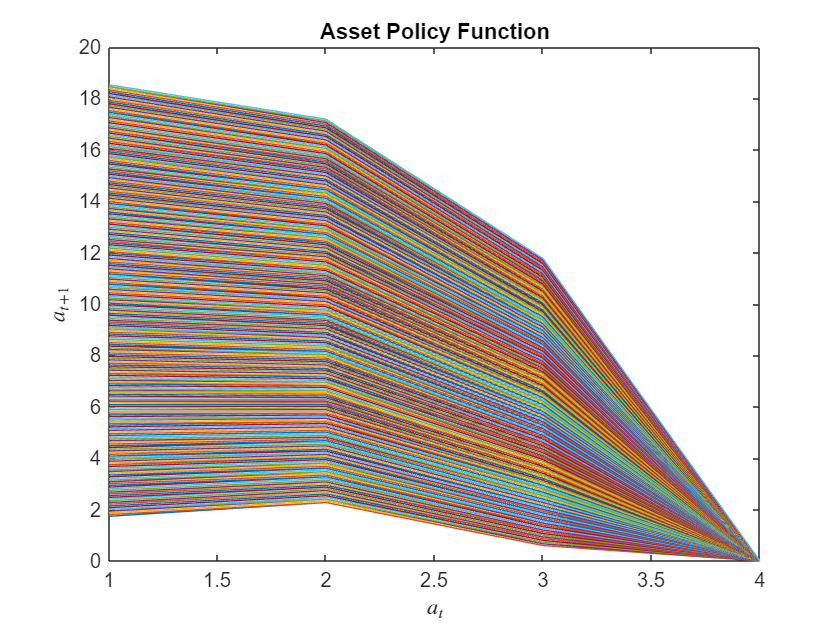

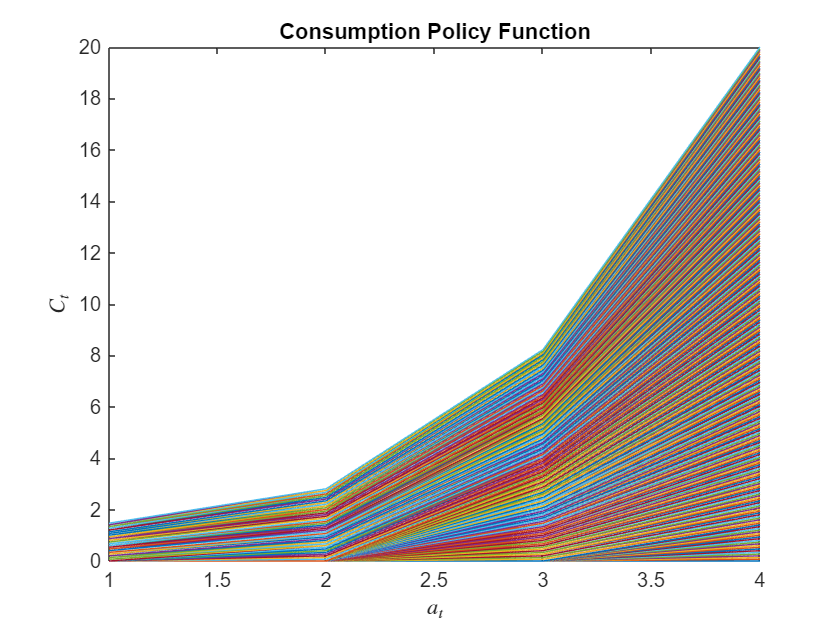

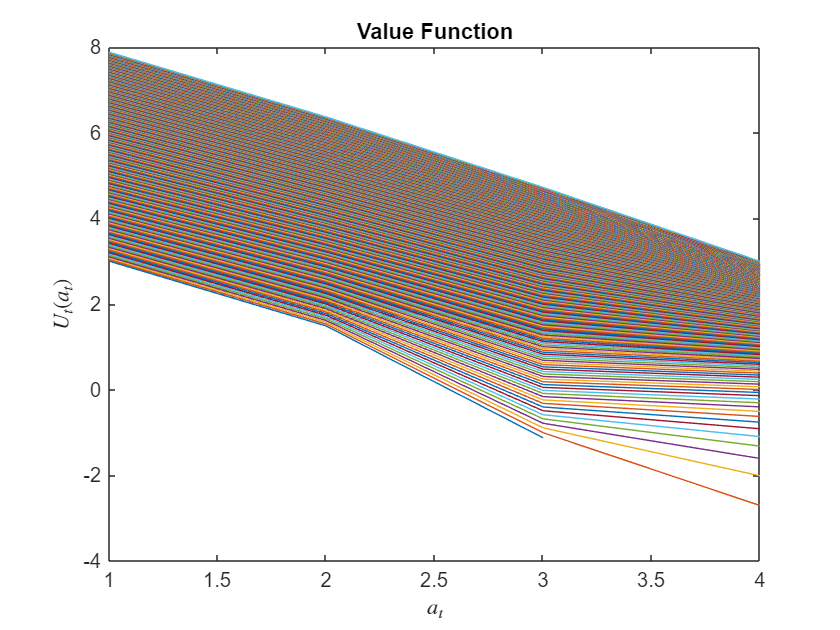

hj_my_graph.plot_policy(par,sol,figout) % Plot the model functions and time series.